# XPlane NN Error Plots

This program aims to provide insight in characterizing the output behahavior of a NN by plotting the output and error in output against state information from randomly generated data. 

clear variables; close all; clc;

## CSV Reader

%Make sure necessary data has been moved over to the MATLAB folder 
csvData1 = readtable('/home/achadbo/XPlaneAutolandScenario/plots/2024-5-23/450/combined_states.csv') %50m, OOD by 0

csvData1 = 74999×8 table
    error_h    error_y      phi       theta       psi          x          y         h   
    _______    _______    _______    _______    ________    _______    _______    ______

    -17.838     5.7772     5.8376    -1.3007    -0.68804    -37.002     73.999    479.24
      16.29    -8.4418    0.69297     6.3457     -8.5868    -99.001    -55.001    377.24
     42.458    0.38079    -4.8731     6.5781      6.4781    -53.001     4.9986    371.24
    -48.423    0.45483     6.3923     6.0025     0.79073    -26.001     55.997    438.24
    -27.564     45.398     2.2328     2.2367      1.5746    -67.002        116    427.24
    -60.072    -1.5246    -3.6772      7.978      -1.249        145         30 

csvData2 = readtable('/home/achadbo/XPlaneAutolandScenario/errors/2024-5-23/450/generated_states.csv')

csvData2 = 74999×3 table
     y_err     h_err_NN    h_err_true
    _______    ________    __________

     68.222     -63.531      -45.693 
    -46.559      3.5992      -12.691 
     4.6178      3.2486      -39.209 
     55.542     -56.171      -7.7472 
       70.6     -27.516     0.047929 
     31.525     -56.819       3.2534 
    -48.783     -64.945      -11.266 
     59.726     -60.597      -18.375 
     62.532     -55.127       11.584 
    -25.741      12.021      -6.2575 
    -12.167    -0.78064      -14.428 
    -21.894      11.633      -26.432 
     25.102     -62.999      -35.952 
    -14.319       34.21       7.1605 
    -48.982     -67.945      -39.584 
    -56.931     -72.498      -23.105 



minlen = min([length(csvData2.y_err) length(csvData1.error_h)])

minlen = 74999

error_h = csvData1.error_h(1:minlen,:); %NN Error, height offset 
error_y = csvData1.error_y(1:minlen,:); %NN Error, crosstrack offset 
y_pred = csvData2.y_err(1:minlen,:); %NN Output- Predicted crosstrack offset 
h_err_pred = csvData2.h_err_NN(1:minlen,:); %NN Output- Predicted height offset
h_err = csvData2.h_err_true(1:minlen,:); %True height error based on state info 

%True State Information 
phi = csvData1.phi(1:minlen,:); %Roll 
theta = csvData1.theta(1:minlen,:); %Pitch 
psi = csvData1.psi(1:minlen,:); %Yaw
x = csvData1.x(1:minlen,:); %Horizontal distance from runway 
y = csvData1.y(1:minlen,:); %True crosstrack offset 
h = csvData1.h(1:minlen,:); %True Height offset 


## Plots 

All distance units are in meters, all angular units are in degrees. 

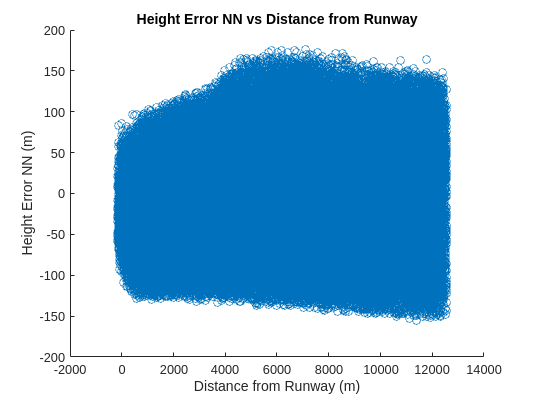

scatter(x, error_h);
axis auto; 
title('Height Error NN vs Distance from Runway');
xlabel('Distance from Runway (m)');
ylabel('Height Error NN (m)');

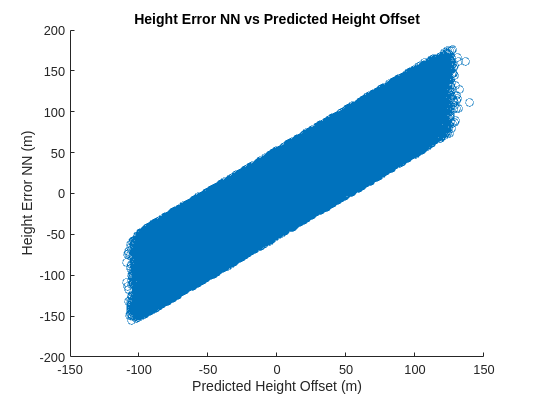


scatter(h_err_pred, error_h);
axis auto; 
title('Height Error NN vs Predicted Height Offset');
xlabel('Predicted Height Offset (m)');
ylabel('Height Error NN (m)');

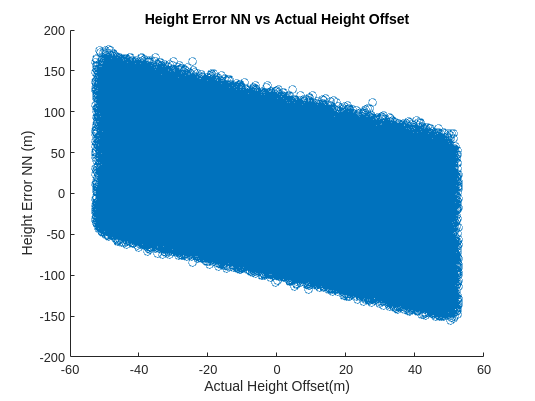


scatter(h_err, error_h);
axis auto; 
title('Height Error NN vs Actual Height Offset');
xlabel('Actual Height Offset(m)');
ylabel('Height Error NN (m)');

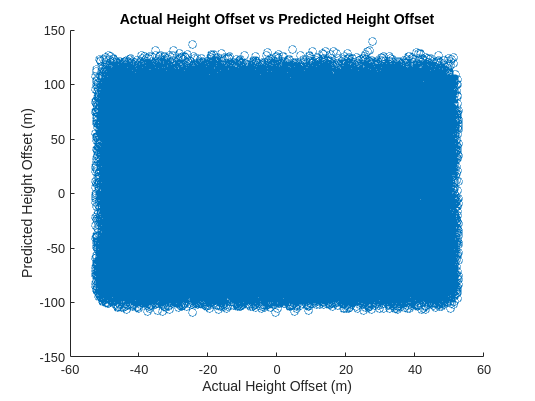


scatter(h_err, h_err_pred);
axis auto; 
title('Actual Height Offset vs Predicted Height Offset');
xlabel('Actual Height Offset (m)');
ylabel('Predicted Height Offset (m)');

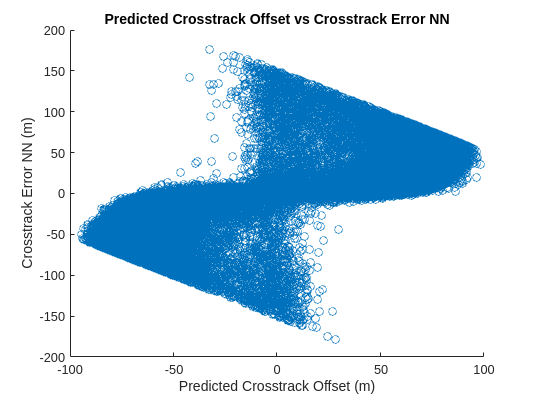


scatter(y_pred, error_y);
axis auto; 
title('Predicted Crosstrack Offset vs Crosstrack Error NN');
xlabel('Predicted Crosstrack Offset (m)');
ylabel('Crosstrack Error NN (m)');

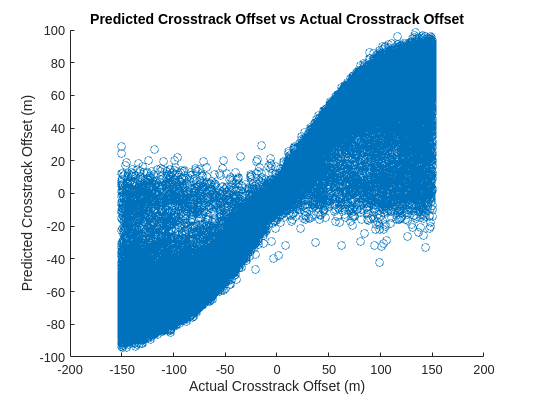


scatter(y, y_pred);
axis auto; 
title('Predicted Crosstrack Offset vs Actual Crosstrack Offset');
xlabel('Actual Crosstrack Offset (m)');
ylabel('Predicted Crosstrack Offset (m)');

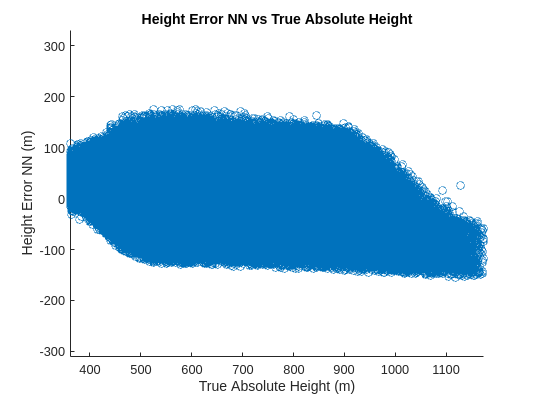


scatter(h, error_h);
axis equal;
title('Height Error NN vs True Absolute Height');
xlabel('True Absolute Height (m)');
ylabel('Height Error NN (m)');

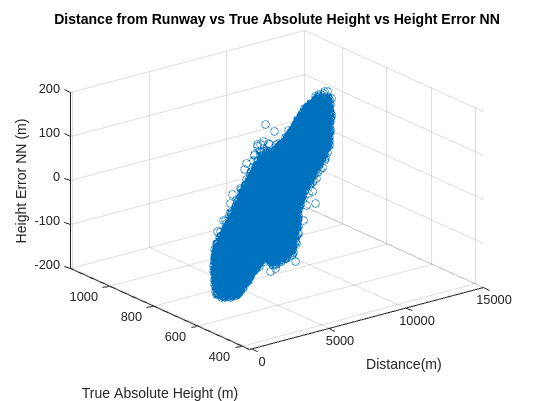


scatter3(x, h, error_h);
%axis equal;
title('Distance from Runway vs True Absolute Height vs Height Error NN');
xlabel('Distance(m)');
ylabel('True Absolute Height (m)');
zlabel('Height Error NN (m)');

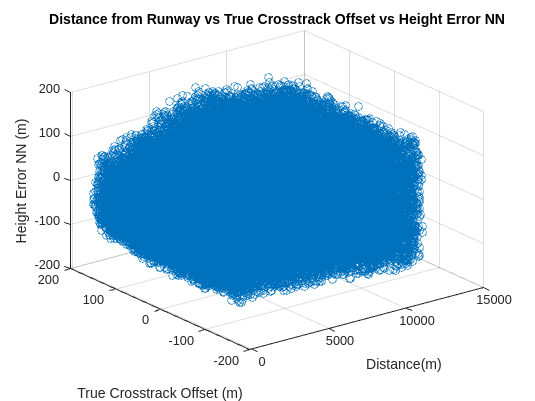


scatter3(x, y, error_h);
%axis equal;
title('Distance from Runway vs True Crosstrack Offset vs Height Error NN');
xlabel('Distance(m)');
ylabel('True Crosstrack Offset (m)');
zlabel('Height Error NN (m)');

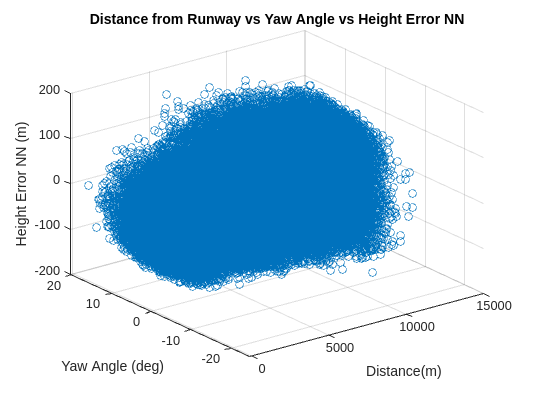


scatter3(x, psi, error_h);
%axis equal;
title('Distance from Runway vs Yaw Angle vs Height Error NN');
xlabel('Distance(m)');
ylabel('Yaw Angle (deg)');
zlabel('Height Error NN (m)');

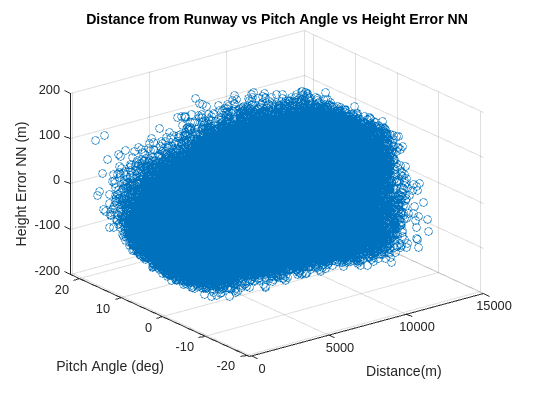


scatter3(x, theta, error_h);
%axis equal;
title('Distance from Runway vs Pitch Angle vs Height Error NN');
xlabel('Distance(m)');
ylabel('Pitch Angle (deg)');
zlabel('Height Error NN (m)');

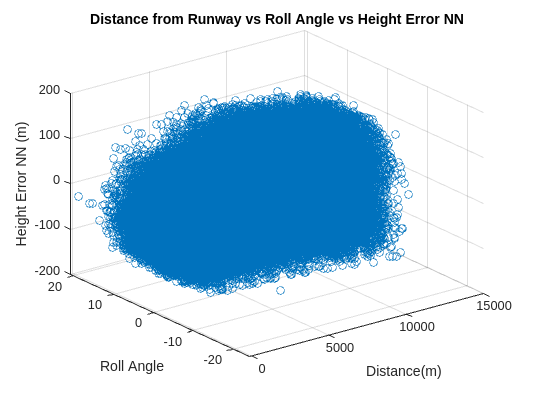



scatter3(x, phi, error_h);
%axis equal;
title('Distance from Runway vs Roll Angle vs Height Error NN');
xlabel('Distance(m)');
ylabel('Roll Angle');
zlabel('Height Error NN (m)');

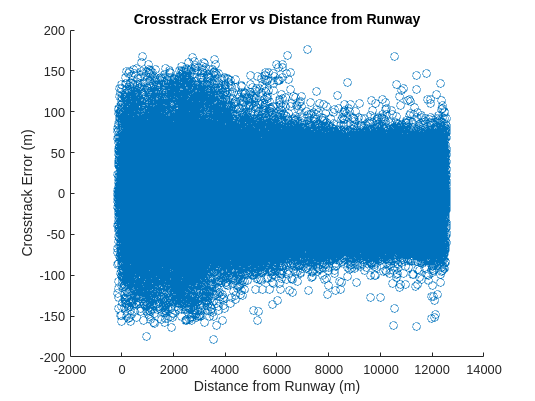


scatter(x, error_y);
axis auto; 
title('Crosstrack Error vs Distance from Runway');
xlabel('Distance from Runway (m)');
ylabel('Crosstrack Error (m)');

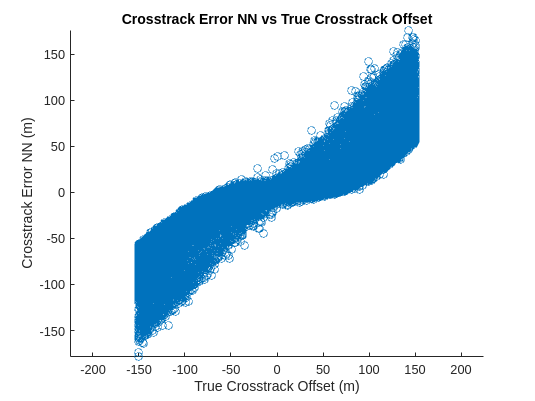


scatter(y, error_y);
axis equal;
title('Crosstrack Error NN vs True Crosstrack Offset');
xlabel('True Crosstrack Offset (m)');
ylabel('Crosstrack Error NN (m)');

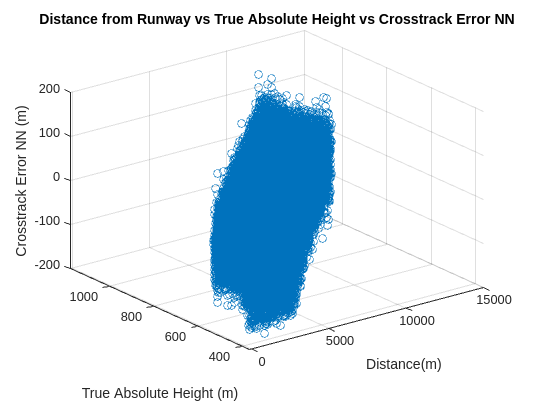


scatter3(x, h, error_y);
%axis equal;
title('Distance from Runway vs True Absolute Height vs Crosstrack Error NN');
xlabel('Distance(m)');
ylabel('True Absolute Height (m)');
zlabel('Crosstrack Error NN (m)');


%%This is the first graph I began bounding on due to its nice shape 

%Sort height values from least to greatest and error values based on corresponding height
%indices 
tab = table(h, error_y); 
tab = sortrows(tab, "h", "ascend")

tab = 74999×2 table
      h       error_y
    ______    _______

    361.02     92.569
    361.06     44.182
    361.06     11.151
    361.09     17.986
    361.13     -114.7
    361.13    -61.465
    361.21    -39.793
    361.24    -21.466
    361.24     110.15
    361.26     6.2927
    361.27    -136.91
    361.27     118.68
     361.3    -69.348
     361.3     98.112
    361.33    -27.716
    361.33    -32.018


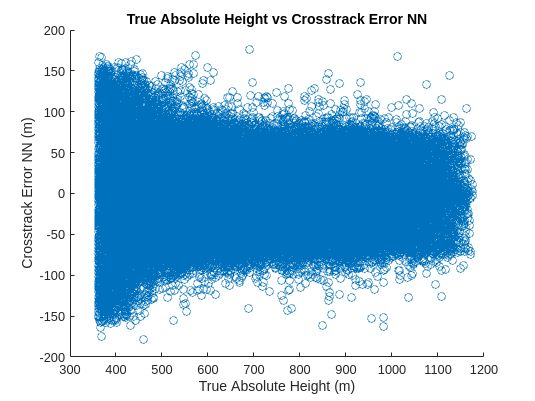


scatter(h, error_y);
%axis equal;
title('True Absolute Height vs Crosstrack Error NN');
xlabel('True Absolute Height (m)');
ylabel('Crosstrack Error NN (m)');


%%This is the best bet so far, find max point within a particular height
%%interval and fit a polynomial piece wise function to it- still working at
%%it a little 
max = 0; 
a = [];
b = []; 

for i = 1:length(h)
    if error_y(i) > max
        max = error_y(i); 
    end 
    if mod(i, 2000) == 0
       a(end+1) = max; 
       b(end + 1) = h(i); 
       max = 0; 
    end 
end 

%Another way to get maxes- find peaks, not as sucessful since doesn't find
%per interval- may just need to get more familar with the function though 
% [pks, locs] = findpeaks(tab.error_y, 'SortStr','descend','NPeaks',5); 
% 
% b = h(locs); 

figure 
a = a(a > 5); 
b = b(a > 5); 
b = b'; 
a = a'; 
scatter(h, error_y); 
xlim([0 1100])
ylim([0, 50])
hold on; 
f = fit(b,a,'pchip')

f =      Shape-preserving (pchip) interpolant:
       f(x) = piecewise polynomial computed from p
       with pchip extrapolation
     Coefficients:
       p = coefficient structure

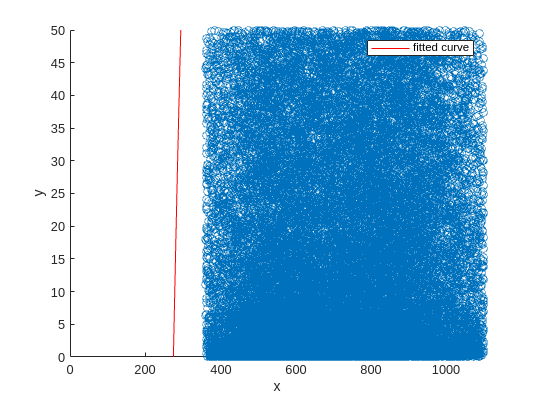

plot(f); 
hold off; 

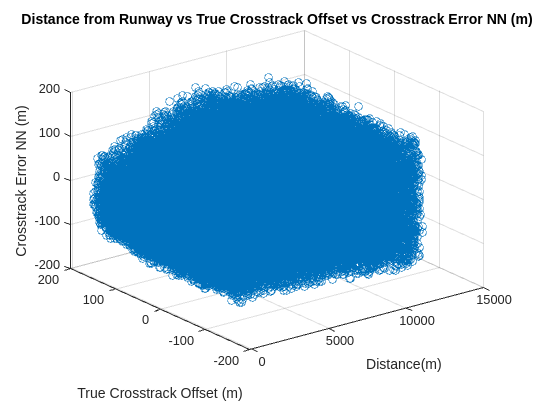


%%Now attempting to use boundary, hasn't worked so far 
% hold on; 
% boundaryline(b, a, "HatchLength",0.000000001);
% hold off; 


scatter3(x, y, error_h);
%axis equal;
title('Distance from Runway vs True Crosstrack Offset vs Crosstrack Error NN (m)');
xlabel('Distance(m)');
ylabel('True Crosstrack Offset (m)');
zlabel('Crosstrack Error NN (m)');

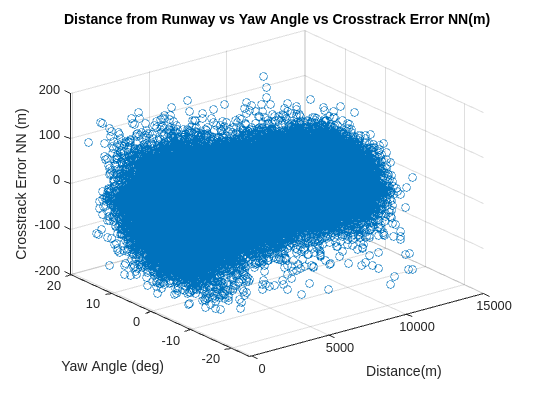


scatter3(x, psi, error_y);
%axis equal;
title('Distance from Runway vs Yaw Angle vs Crosstrack Error NN(m)');
xlabel('Distance(m)');
ylabel('Yaw Angle (deg)');
zlabel('Crosstrack Error NN (m)');

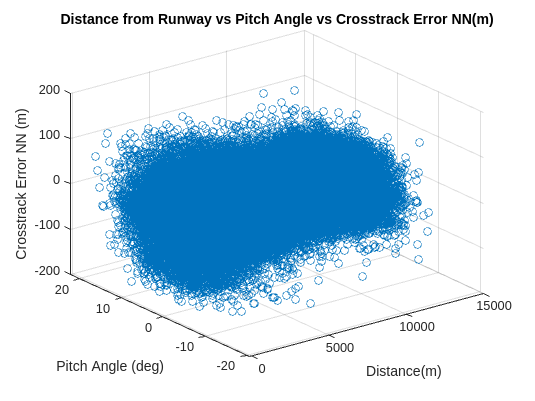


scatter3(x, theta, error_y);
%axis equal;
title('Distance from Runway vs Pitch Angle vs Crosstrack Error NN(m)');
xlabel('Distance(m)');
ylabel('Pitch Angle (deg)');
zlabel('Crosstrack Error NN (m)');

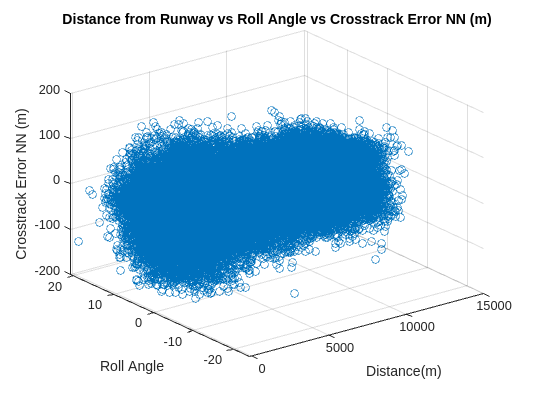



scatter3(x, phi, error_y);
%axis equal;
title('Distance from Runway vs Roll Angle vs Crosstrack Error NN (m)');
xlabel('Distance(m)');
ylabel('Roll Angle');
zlabel('Crosstrack Error NN (m)');